% %PID Regler Entwurf

R = 0.398/2

R = 0.1990

L = 876e-6/2; 
Ts = 1e-5

Ts = 1.0000e-05

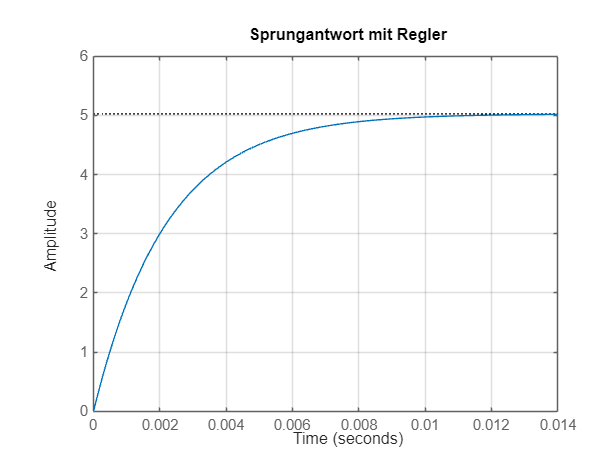


s = tf('s');
GS1 = 1/(L*s+R);

% Regler: PID (automatisch abgestimmt)
GR1 = pid(1,10,0);

% Geschlossener Kreis mit Einheitssensor
GRKI = feedback(GR1*GS1, 1);

% Sprungantwort plotten
figure; step(GS1); grid on; title('Sprungantwort mit Regler');


% Kennwerte ausgeben
info = stepinfo(GRKI)

info = struct with fields:
         RiseTime: 0.0590
    TransientTime: 0.2515
     SettlingTime: 0.2515
      SettlingMin: 0.9000
      SettlingMax: 0.9971
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9971
         PeakTime: 0.4829


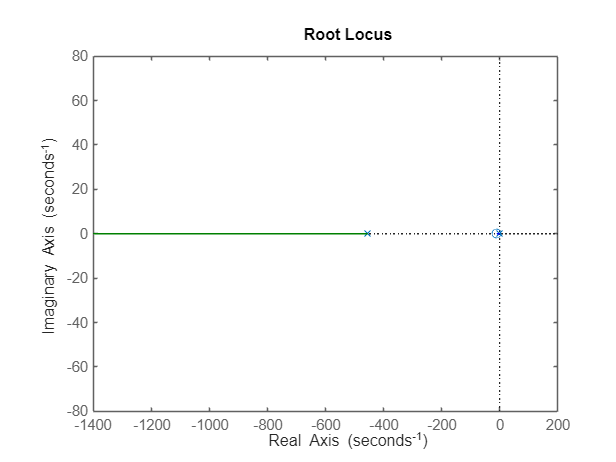


rlocus(GR1*GS1)



% Discrete
GS1_D = c2d(GS1,Ts,'tustin')

GS1_D =
 
  0.01139 z + 0.01139
  -------------------
      z - 0.9955
 
Sample time: 1e-05 seconds
Discrete-time transfer function.
Model Properties


GR1_D = c2d(GR1,Ts,'tustin')

GR1_D =
 
            Ts*(z+1)
  Kp + Ki * --------
            2*(z-1) 

  with Kp = 1, Ki = 10, Ts = 1e-05
 
Sample time: 1e-05 seconds
Discrete-time PI controller in parallel form.
Model Properties


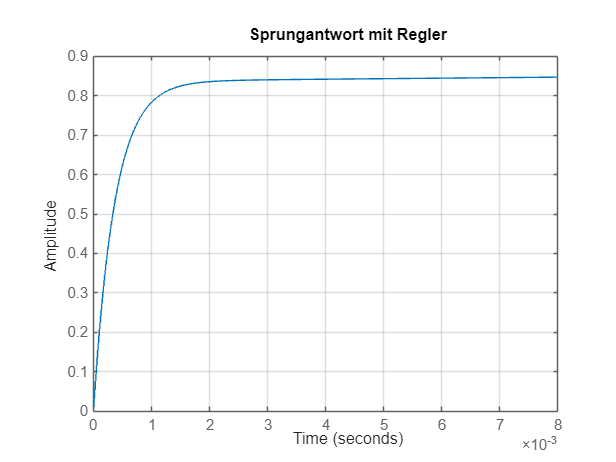


[numR, denR] = tfdata(GR1_D, 'v');
writematrix(numR(:), "GR1D_num.csv", "Delimiter", ";");
writematrix(denR(:), "GR1D_den.csv", "Delimiter", ";");

GRKI_D = feedback(GR1_D*GS1_D, 1);

% Sprungantwort plotten
figure; step(GRKI_D); grid on; title('Sprungantwort mit Regler');


% Kennwerte ausgeben
info = stepinfo(GRKI_D)

info = struct with fields:
         RiseTime: 8.7000e-04
    TransientTime: 0.0020
     SettlingTime: 0.0020
      SettlingMin: 0.7685
      SettlingMax: 0.8522
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8522
         PeakTime: 0.0124


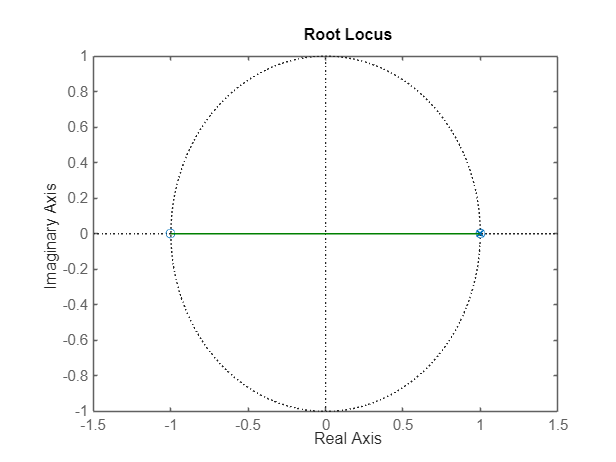


rlocus(GR1_D*GS1_D)

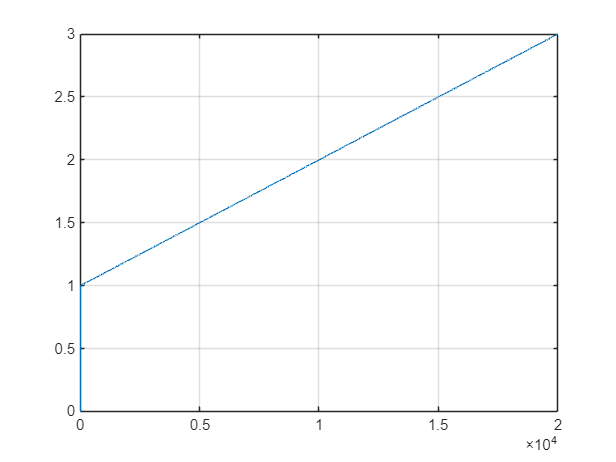



N = 20000;
e = ones(N,1);   % step error
e(1,1) = 0;
u_mat = lsim(GR1_D, e);
plot(u_mat); grid on